## Taller 11 - Ecuaciones diferenciales

### Modelo epidemiológico SIRV

**Estudiante**: Daniela Córdoba Hamid

**C.C:** 1001015774

**Introducción**

Las ecuaciones diferenciales son herramientas que permiten analizar e incluso predecir el comportamiento de diversidad de modelos dinámicos reales, por ejemplo el modelo epidemiológico SIRV; este modelo permite estudiar la propagación de enfermedades, obteniendo una importante cantidad de información sobre la dinámica de una enfermedad y las posibles estrategias para la intervención y contención de esta.

En el presente taller se abordará la solución del sistema de ecuaciones diferenciales de un modelo epidemiológico, así como el análisis del comportamiento de este al momento de cambiar los diferentes factores que lo afectan, utilizando el software MATLAB.

El modelo SIRV explica la evolución de una enfermedad infecciosa creada por algún patógeno, tal como un virus o una bacteria, y consiste de un sistema de ecuaciones diferenciales ordinarias no lineales que permiten hacer una predicción aproximada del comportamiento de la enfermedad a lo largo del tiempo. Para facilitar el análisis del comportamiento de la enfermedad dentro de la población, el modelo separa la población total en 4 grupos:

- $S\left(t\right)$: representa el número de individuos dentro de la población que son susceptibles a la enfermedad, es decir, individuos sanos que al entrar en contacto con esta pueden resultar infectados.

- $I\left(t\right)$: representa el número de individuos infectados por la enfermedad, los cuales pueden transmitirla al grupo de individuos susceptibles.

- $R\left(t\right)$: representa el número de individuos recuperados de la enfermedad, ya sea que se han vuelto inmunes o han fallecido.

- $V\left(t\right)$: representa el número de individuos que han sido vacunados contra el patógeno que genera la enfermedad.

Además de lo anterior, este modelo se basa en las siguientes hipótesis:

- La población se mantiene constante, es decir que dentro de este modelo no se tienen en cuenta nacimientos y muertes ocurridas a lo largo del tiempo en el que se desarrolla la enfermedad. Al denotar dicha población como $N$, se obtiene entonces que la suma de cada uno de los grupos anteriores es igual a la población total:


$$N=S\left(t\right)+I\left(t\right)+R\left(t\right)+V\left(t\right)$$


- La enfermedad es transmitida por contacto directo entre los individuos.

- La tasa de infección, la cual determina el número de individuos que a lo largo del tiempo pasan de ser susceptibles a infectados, es proporcional al producto $S\left(t\right)*I\left(t\right)$

A partir de las hipótesis y grupos planteados, es posible formular el modelo:


$$S^{\prime } =-\beta \;S\left(t\right)\;I\left(t\right)-\delta \;S\left(t\right)$$



$$I^{\prime } =\beta \;S\left(t\right)\;I\left(t\right)-\gamma \;I\left(t\right)$$



$$R^{\prime } =\gamma \;I\left(t\right)$$



$$V^{\prime } =\delta \;S\left(t\right)$$


Donde $\beta$ es la tasa de transmisión de la enfermedad, $\gamma$ es la tasa de recuperación y $\delta$ es la tasa de vacunación.

Inicialmente se realizará la solución de este sistema de ecuaciones tomando los valores para cada uno de los parámetros $\beta$, $\gamma$ y $\delta$ los valores especificados dentro del taller; los cuales, al realizar el cálculo del número reproductivo básico Ro, se obtiene que para el caso a estudiar es una epidemia.

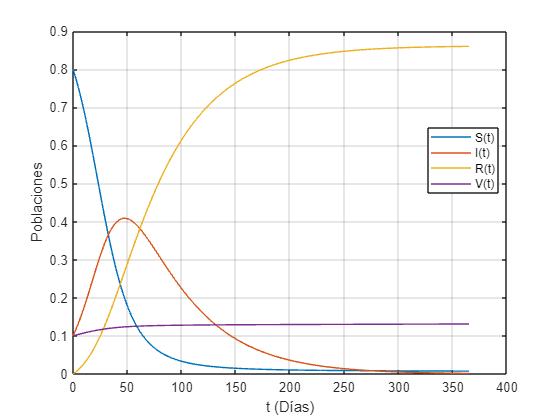

syms S(t) I(t) R(t) V(t)

%Parámetros del modelo
beta1 = 0.1; 
gamma = 0.02; 
delta = 0.001;

%Funciones
f1 = -beta1*S*I - delta*S;
f2 = beta1*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

%Convierte a función de MATLAB para ode45
f = odeFunction([f1 f2 f3 f4],[S I R V]);

%Paso para el cálculo de la solución numérica
h = 1; 

%Intervalo de tiempo
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax; 

%Condiciones iniciales S I R V
CI = [0.8 0.1 0 0.1]; 
[t1,x1] = ode45(f,tspan,CI); 

plot(t1,x1)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

Debido a que se busca analizar cómo la población de vacunados puede afectar el comportamiento de todo el modelo, se realizará el mismo cálculo sin variar ninguno de los parámetros $\beta$, $\gamma$, $\delta$ pero alterando la cantidad de individuos dentro de la población que se encuentran vacunados inicialmente.

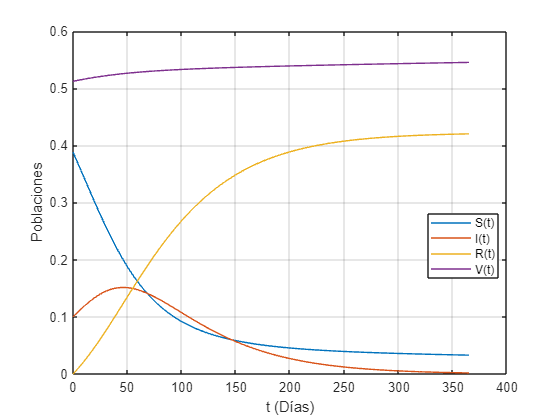

%Cambiando la condición inicial para V(t)
v0 = 0.512; 
CI = [0.9-v0  0.1  0  v0]; 
[t2,x2] = ode45(f,tspan,CI);
plot(t2,x2)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

Comparando entonces ambas gráficas y el comportamiento de cada uno de los grupos, se puede apreciar inmediatamente que el número de individuos susceptibles bajó considerablemente en comparación a la primera gráfica realizada, pudiendo concluir entonces que el aumento significativo que se dio en la cantidad de inviduos vacunados permitió que se disminuyera el impacto del patógeno sobre la población analizada; además de esto, se obtuvo que teniendo aproximadamente un 50% de la población vacunada contra la enfermedad, es posible disminuir el pico de individuos infectados casi a un 15% de la población.

Posterior a esto se busca analizar cómo es el impacto de la cantidad inicial de individuos infectados en el desarrollo de la enfermedad a lo largo del tiempo, teniendo siempre en cuenta que una de las hipótesis que se deben de cumplir para poder analizar este modelo es que el tamaño de la población siempre debe de mantenerse constante, es decir que se debe de cumplir la expresión $N=S\left(t\right)+I\left(t\right)+R\left(t\right)+V\left(t\right)$.

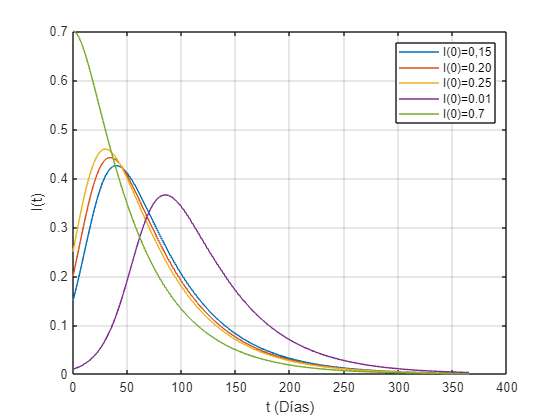

syms S(t) I(t) R(t) V(t)
% Parámetros del modelo
beta = 0.1; 
gamma = 0.02; 
delta = 0.001; 

%Funciones
f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);

% Parámetros de tiempo 
h = 1; 
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax; 

%Condiciones iniciales, la suma debe ser 1
ci1 = [0.75  0.15  0  0.1]; 
ci2 = [0.7   0.20  0  0.1]; 
ci3 = [0.65  0.25  0  0.1];
ci4 = [0.89  0.01  0  0.1]; 
ci5 = [0.2   0.7   0  0.1]; 

%Cálculo de ecuaciones con cada condición inicial
[t1,x1] = ode45(f,tspan,ci1);
[t2,x2] = ode45(f,tspan,ci2);
[t3,x3] = ode45(f,tspan,ci3);
[t4,x4] = ode45(f,tspan,ci4);
[t5,x5] = ode45(f,tspan,ci5);


plot(t1,x1(:,2), t2,x2(:,2), t3,x3(:,2), t4,x4(:,2), t5,x5(:,2))
xlabel('t (Días)')
ylabel('I(t)')
grid on
legend({'I(0)=0,15','I(0)=0.20','I(0)=0.25','I(0)=0.01','I(0)=0.7'})

Al aumentar la cantidad de individuos infectados inicialmente, es necesario variar alguno de los otros valores iniciales para mantener constante la cantidad de individuos totales dentro de la población; por tanto, y para simplificar un poco el proceso de análisis, se decidió mantener constante la cantidad de individuos vacunados y variar la cantidad de individuos susceptibles a la enfermedad. Como se puede apreciar en la gráfica, al aumentar la cantidad de individuos enfermos para el primer instante de análisis, genera que a lo largo del tiempo el pico máximo de infectados sea significativamente mayor; sin embargo, se puede ver que para los valores más altos de infectados, este pico disminuye más rápido que para valores más pequeños, esto se debe a que también es necesario tener en cuenta la cantidad de individuos que son susceptibles a la enfermedad, por lo cual al tener una mayor cantidad de individuos susceptibles a infectarse, el virus tardará mucho más tiempo en desaparecer mientras que cada uno de estos individuos pasa a hacer parte de la población de individuos recuperados.

Ahora, la cantidad inicial de individuos pertenecientes a cada uno de los grupos en los que fue separada la población total no es el único parámetro que afecta el comportamiento del modelo, ya que este depende en gran medida de las diferentes tasas que lo acompañan. Inicialmente se analizará el comportamiento de este cuando varía el valor de la tasa de transmisión del virus.

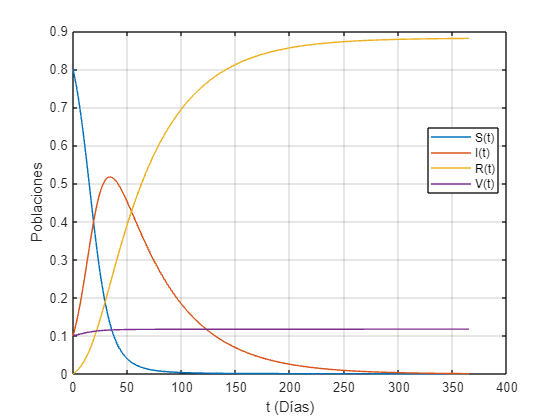

syms S(t) I(t) R(t) V(t)

h = 1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%Beta de 0.15
beta = 0.15; 
gamma = 0.02; 
delta = 0.001;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]); 
CI = [0.8 0.1 0 0.1]; 
[t1,x1] = ode45(f,tspan,CI);

plot(t1,x1)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

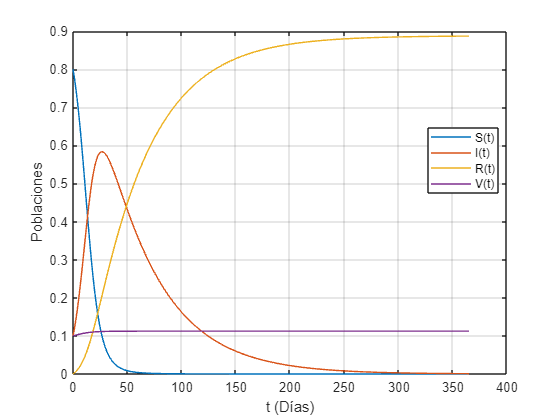

%Beta de 0.20
beta = 0.20; 
gamma = 0.02; 
delta = 0.001;
f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t2,x2] = ode45(f,tspan,CI);

plot(t2,x2)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

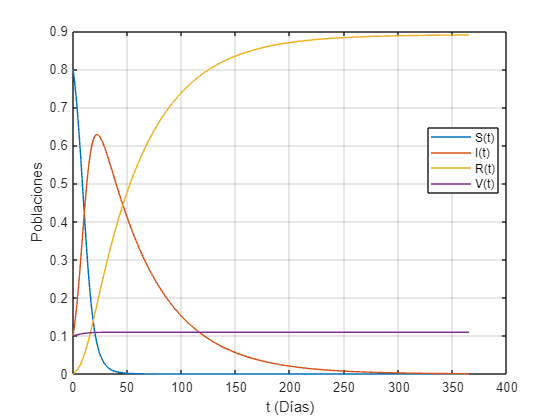

%Beta de 0.25
beta = 0.25; 
gamma = 0.02; 
delta = 0.001; 

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t3,x3] = ode45(f,tspan,CI);

plot(t3,x3)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

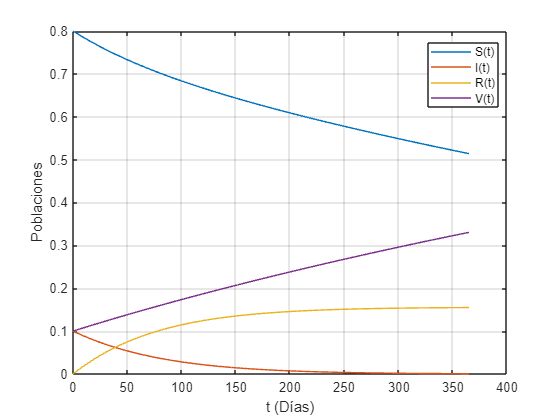

%Beta de 0.01
beta = 0.01; 
gamma = 0.02; 
delta = 0.001;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1];
[t4,x4] = ode45(f,tspan,CI);

plot(t4,x4)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

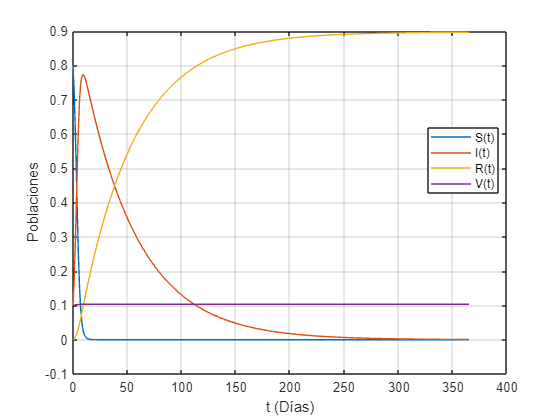

%Beta de 0.7
beta = 0.7; 
gamma = 0.02; 
delta = 0.001;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;
f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t5,x5] = ode45(f,tspan,CI);

plot(t5,x5)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

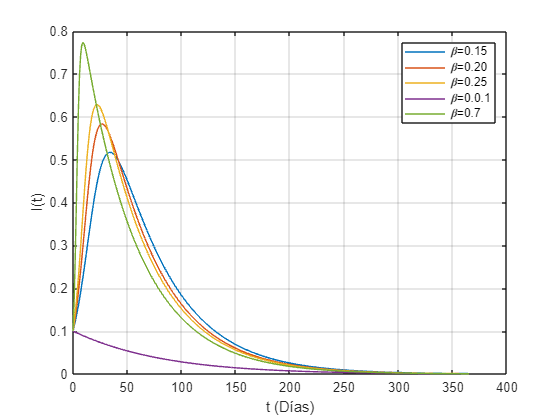

plot(t1,x1(:,2),t2,x2(:,2),t3,x3(:,2),t4,x4(:,2),t5,x5(:,2))
xlabel('t (Días)')
ylabel('I(t)')
grid on
legend({'\beta=0.15','\beta=0.20','\beta=0.25','\beta=0.0.1','\beta=0.7'})

Cuando se habla de tasa de transmisión, se refiere a la capacidad del patógeno para propagarse en la población, es decir un promedio de la cantidad de individuos dentro del grupo de susceptibles a las que un individuo enfermo puede infectar; entonces, al mirar las diferentes gráficas para $I\left(t\right)$ se puede apreciar inmediatamente que mientras menor sea el valor que corresponde a la tasa de transmisión, menor va a ser la cantidad de individuos infectados a lo largo del tiempo. Por lo tanto, si lo que se busca es evitar un mayor impacto en la población debido a una epidemia de la enfermedad, es necesario disminuir al máximo el valor de $\beta$, en el caso de la gráfica sería un valor de 0.01, para evitar obtener un pico de infectados y disminuir la cantidad de individuos enfermos a lo largo del tiempo, incluso si el número de individuos afectados inicialmente es significativamente alto.

Ya conociendo entonces cómo se comporta el modelo cuando presenta un cambio en la tasa de transmisión, se puede proceder a realizar cambios en el valor que corresponde a la tasa de recuperanción.

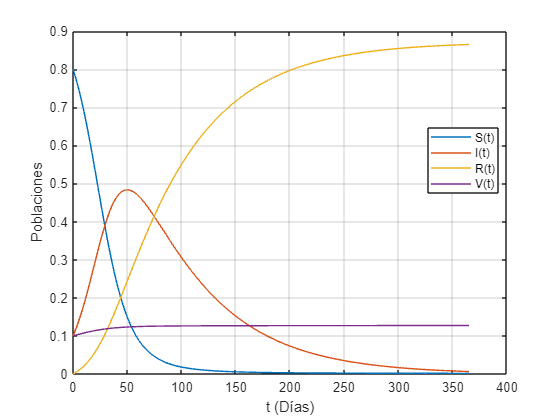

syms S(t) I(t) R(t) V(t)

h = 1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%Gamma de 0.015
beta = 0.1; 
gamma = 0.015; 
delta = 0.001;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]); 
CI = [0.8 0.1 0 0.1]; 
[t1,x1] = ode45(f,tspan,CI);

plot(t1,x1)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

%Gamma de 0.020
beta = 0.1; 
gamma = 0.020; 
delta = 0.001;
f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t2,x2] = ode45(f,tspan,CI);

plot(t2,x2)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

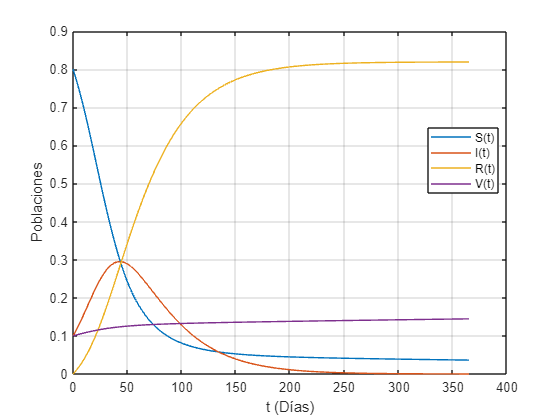

%Gamma de 0.03
beta = 0.1; 
gamma = 0.03; 
delta = 0.001; 

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t3,x3] = ode45(f,tspan,CI);

plot(t3,x3)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

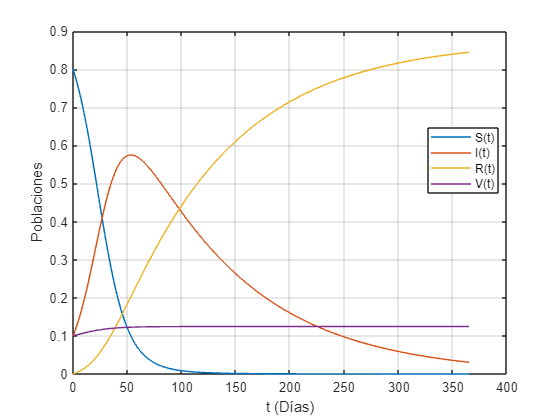

%Gamma de 0.01
beta = 0.1; 
gamma = 0.01; 
delta = 0.001;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1];
[t4,x4] = ode45(f,tspan,CI);

plot(t4,x4)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

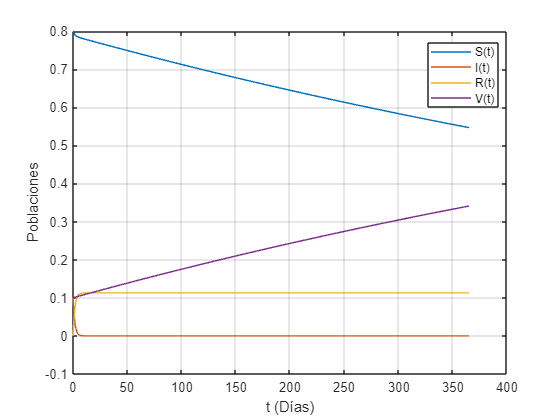

%Gamma de 0.7
beta = 0.1; 
gamma = 0.7; 
delta = 0.001;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;
f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t5,x5] = ode45(f,tspan,CI);

plot(t5,x5)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

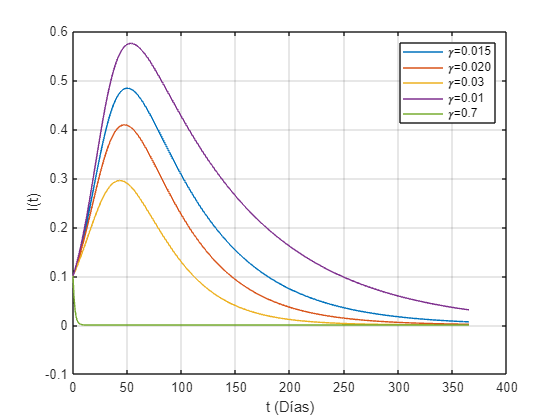

plot(t1,x1(:,2),t2,x2(:,2),t3,x3(:,2),t4,x4(:,2),t5,x5(:,2))
xlabel('t (Días)')
ylabel('I(t)')
grid on
legend({'\gamma=0.015','\gamma=0.020','\gamma=0.03','\gamma=0.01','\gamma=0.7'})

A diferencia del parámetro $\beta$, al observar el comportamiento de la curva de infectados con cada uno de los diferentes valores de $\gamma$ se puede evidenciar que al aumentar el valor de la tasa de recuperación, la curva de infectados disminuye significativamente, ya que este valor representa cuánto es el porcentaje de individuos que logran superar la infección y pasar al grupo de individuos recuperados; por lo tanto, al aumentar el valor de esta tasa se logra controlar el progreso de la enfermedad, como en el caso que se puede apreciar en la gráfica, cuyo valor de $\gamma =0\ldotp 7$ generó una disminución casi inmediata de la curva de infectados. En situaciones donde se presenta una epidemia de algún tipo de enfermedad, se busca entonces aumentar este valor por medio de los diferentes tratamientos que se encuentren disponibles para tratar la enfermedad en cuestión.

Finalmente, se puede realizar el análisis del comportamiento del modelo epidemiológico cuando varía su tasa de vacunación. 

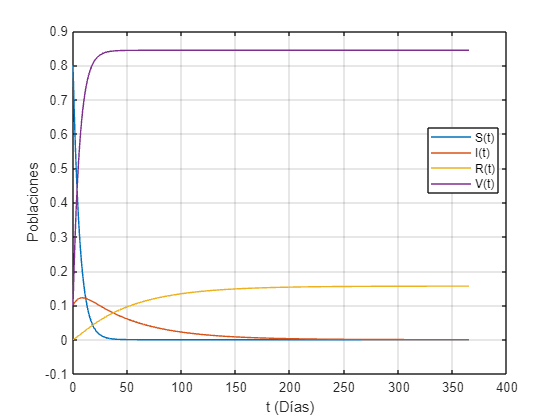

syms S(t) I(t) R(t) V(t)

h = 1;
tmin = 0;
tmax = 365;
tspan = tmin:h:tmax;

%Delta de 0.15
beta = 0.1; 
gamma = 0.02; 
delta = 0.15;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]); 
CI = [0.8 0.1 0 0.1]; 
[t1,x1] = ode45(f,tspan,CI);

plot(t1,x1)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

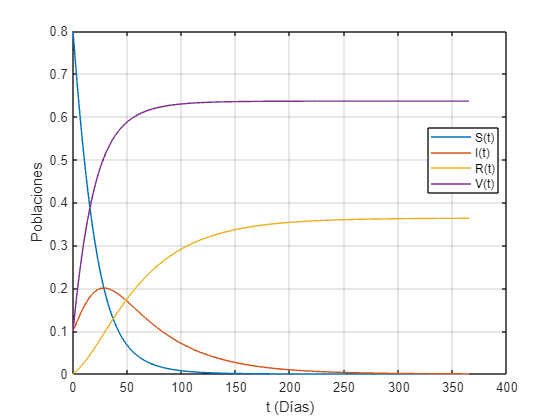


%Delta de 0.032
beta = 0.1; 
gamma = 0.02; 
delta = 0.032;
f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t2,x2] = ode45(f,tspan,CI);

plot(t2,x2)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

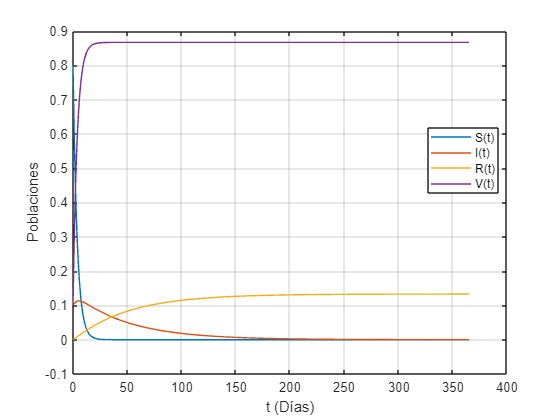


%Delta de 0.25
beta = 0.1; 
gamma = 0.02; 
delta = 0.25; 

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t3,x3] = ode45(f,tspan,CI);

plot(t3,x3)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

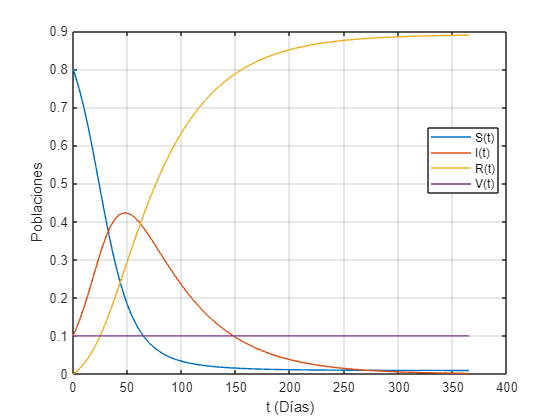


%Delta de 0
beta = 0.1; 
gamma = 0.02; 
delta = 0;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;

f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1];
[t4,x4] = ode45(f,tspan,CI);

plot(t4,x4)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

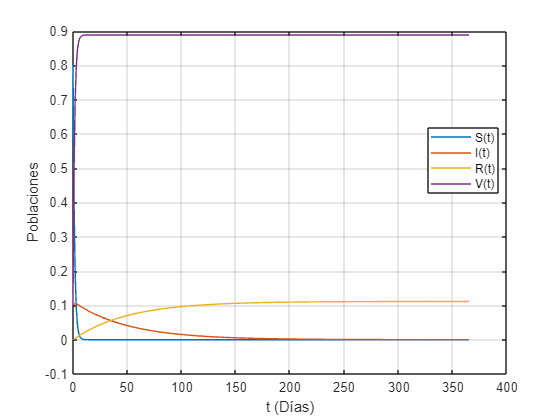


%Delta de 0.7
beta = 0.1; 
gamma = 0.02; 
delta = 0.7;

f1 = -beta*S*I - delta*S;
f2 = beta*S*I - gamma*I;
f3 = gamma*I; 
f4 = delta*S;
f = odeFunction([f1 f2 f3 f4],[S I R V]);
CI = [0.8 0.1 0 0.1]; 
[t5,x5] = ode45(f,tspan,CI);

plot(t5,x5)
xlabel('t (Días)')
ylabel('Poblaciones')
grid on
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location','Best')

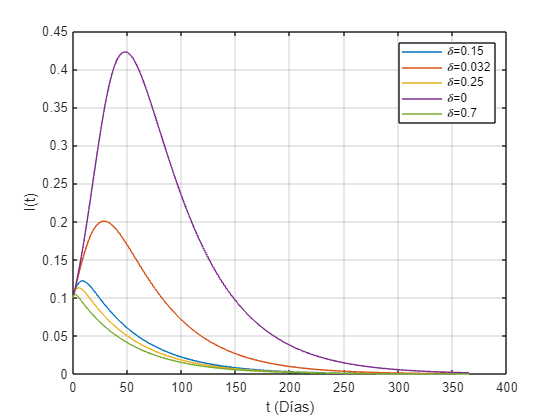


plot(t1,x1(:,2),t2,x2(:,2),t3,x3(:,2),t4,x4(:,2),t5,x5(:,2))
xlabel('t (Días)')
ylabel('I(t)')
grid on
legend({'\delta=0.15','\delta=0.032','\delta=0.25','\delta=0','\delta=0.7'})

La tasa de vacunación es un parámetro supremamente importante, ya que este permite medir el grado de inmunización de la población contra el virus que la afecta; ahora bien, al observar el comportamiento de las gráficas correspondientes a la población infectada, se aprecia que mientras más alta sea dicha tasa de vacunación, menor será el porcentaje de individuos infectados que se presentará dentro de la población a lo largo del tiempo, ya que este disminuye en gran medida la cantidad de individuos susceptibles a la enfermedad. Si se desea entonces obtener un pico de infectados que corresponda aproximadamente al 20% de la población, es necesario tener una tasa de vacunación aproximada de $\delta =0\ldotp 032$; sin embargo, lo ideal debería de ser siempre llevar este valor al máximo posible.

**Conclusión**

En conclusión, por medio del presente taller se pudo observar cómo una ecuación diferencial puede modelar el comportamiento de diversidad de sistemas dinámicos reales, en este caso el modelo SIRV que representa la propagación de una enfermedad, y cómo este se ve influenciado por los diversos parámetros que lo conforman; gracias a esto fue posible realizar un análisis de la importancia tanto de los grupos en los que se divide una población como de las tasas que afectan el comportamiento de estos a lo largo del tiempo. Los resultados obtenidos a través de este sistema de ecuaciones diferenciales permiten predecir cómo será el desarrollo de una epidemia en la realidad, facilitanto la generación de estrategias de control y prevención de esta en caso de que sea necesario.